## CE640 / OC512

### Week 4 - Part 1. File Input

This week we are going to be talking about file input and output. Matlab excels and working with 'data.' And we have learned about many different kinds of 'data' (integers, floats, strings, and so on). Commonly, we have data in the form of a file (either ASCII or binary) and we wish to read that data into Matlab so that we can do something useful with it. And then, after doing something useful with the data, we may wish to write that (new) data out to a different file.

It is critical that you get good at working with files. Later this term, we will return to file I/O a bit and specifically talk about some common binary file formate (netcdf, hdf5, etc.). For today's class we are going to focus exclusively on 'text' (ascii) files. With one exception...we will also work with excel spreadsheets a bit. While spreadsheets LOOK LIKE basic text, that is only after you have opened the file. The native format of a .xlsx file is binary data. In other words, you definitely can not open up an .xlsx with notepad or some other simple text editor.

clear all
clc

## BLOCK 1 - LOAD

Load has two functions in Matlab. First, if you save a variable using the 'save' command in Matlab, it creates a binary (.mat) file.

%create data, save it, clear the variable, and then re-load it.
x=2;
save test.mat x
clear x
load test.mat
x

x = 2

Ok, the OTHER function of 'load' is to try and load a simple text file. This is a very basic function that has quite a few restrictions. Take a look at the file I display below. It contains tab-delimited text (numbers only) and it has header rows that are 'commented' out with the % symbol.

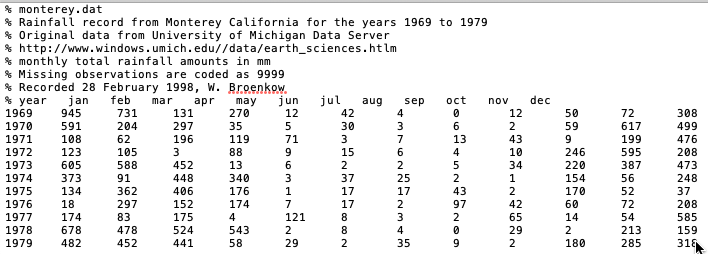

%Let's load this data in...
tic
data=load('monterey.dat')

data =         1969         945         731         131         270          12          42           4           0          12          50          72         308
        1970         591         204         297          35           5          30           3           6           2          59         617         499
        1971         108          62         196         119          71           3           7          13          43           9         199         476
        1972         123         105           3          88           9          15           6           4          10         246         595         208
        1973         605         588         452          13           6           2           2           5          34         220         387         473
        1974         373          91         448         340           3          37          25           2           1         154          56         248
        1975         134         362         406   

disp(['time with load = ' num2str(toc)])

time with load = 0.053249


So, if you have a super simple file with just numbers, and possibly header lines, this can work well. But, there are many other ways to do this.

## BLOCK 2 - DLMREAD

DLMREAD - works on delimited ascii files. No headers allowed. Note that you can 'subset' the data and only read in portions. You can specify the delimeter (space, comma, tab, etc.) but if you do not, Matlab will try to figure it out. Below, I test this out on a different ascii text file; same file as above, but this time with no headers. I will read in the data twice. The first time, I will read in everything. The second time, I will read in only a subset. The syntax is [rowstart columnstart rowend columnend]. Note that in this case, Matlab starts its counting at 0.

clear all
tic
data=dlmread('monterey_nohead.txt')

data =         1969         945         731         131         270          12          42           4           0          12          50          72         308
        1970         591         204         297          35           5          30           3           6           2          59         617         499
        1971         108          62         196         119          71           3           7          13          43           9         199         476
        1972         123         105           3          88           9          15           6           4          10         246         595         208
        1973         605         588         452          13           6           2           2           5          34         220         387         473
        1974         373          91         448         340           3          37          25           2           1         154          56         248
        1975         134         362         406   

disp(['time with dkmread = ' num2str(toc)]) 

time with dkmread = 0.39781


%It is useful to compare how much time it takes. 
%Not a big deal here, but reading in LARGE files can take FOREVER.
data_sub=dlmread('monterey_nohead.txt','\t',[6 0 10 1]) %weird that it starts counting at 0. Read first 2 columns of bottom 5 rows.

data_sub =         1975         134
        1976          18
        1977         174
        1978         678
        1979         482


## BLOCK 3 - CSVREAD

CSVREAD - csv files are incredibly common in science and CSVREAD is dedicated to just these files! Again, no headers allowed here. Only numeric data, and it must be separated by commas. You can subset and read in only a portion of a file. Missing entries will be filled with zeros.

clear all
tic
data_csv=csvread('monterey_nohead.csv')

data_csv =         1969         945         731         131         270          12          42           4           0          12          50          72         308
        1970         591         204         297          35           5          30           3           6           2          59         617         499
        1971         108          62         196         119          71           3           7          13          43           9         199         476
        1972         123         105           3          88           9          15           6           4          10         246         595         208
        1973         605         588         452          13           6           2           2           5          34         220         387         473
        1974         373          91         448         340           3          37          25           2           1         154          56         248
        1975         134         362         40

disp(['time with csvread = ' num2str(toc)])

time with csvread = 0.23684


## BLOCK 4 - IMPORTDATA

IMPORTDATA - this is a fairly flexible function that can be used to read in a wide variety of file types, including images like .jpg files. For ascii text files, it works for rectangular matrices of numbers. You CAN have header lines, but you need to tell the function how many you have. Also, it is possible to have different column delimiters (space, tab, comma) and you have to specify that. So, let us go back to the first file that we worked with (8 header rows; tab delimited) and try it out.

clear all
tic
data_ID=importdata('monterey.dat','\t',8); %tab delim; 8 header lines in this case.
disp(['time with importdata = ' num2str(toc)])

time with importdata = 0.21388


Now, one interesting thing here is that the data are returned in a structure. We can separately examine the 'numeric' data and the 'text' data with the following:

data_ID.data

ans =         1969         945         731         131         270          12          42           4           0          12          50          72         308
        1970         591         204         297          35           5          30           3           6           2          59         617         499
        1971         108          62         196         119          71           3           7          13          43           9         199         476
        1972         123         105           3          88           9          15           6           4          10         246         595         208
        1973         605         588         452          13           6           2           2           5          34         220         387         473
        1974         373          91         448         340           3          37          25           2           1         154          56         248
        1975         134         362         406    

data_ID.textdata

ans = 8×1 cell array
    {'% monterey.dat'                                                                    }
    {'% Rainfall record from Monterey California for the years 1969 to 1979'             }
    {'% Original data from University of Michigan Data Server                           '}
    {'% http://www.windows.umich.edu//data/earth_sciences.htlm                          '}
    {'% monthly total rainfall amounts in mm  '                                          }
    {'% Missing observations are coded as 9999                                          '}
    {'% Recorded 28 February 1998, W. Broenkow                      '                    }
    {'% year   jan   feb   mar   apr   may   jun   jul   aug   sep   oct   nov   dec'    }


All of the header lines get lumped into the textdata field.

## BLOCK 5 - TDFREAD

TDFREAD - this reads in only tab delimited data. The first row needs to have variable names, the other rows contain the data. TDFREAD will look at the variable types. If a column is numbers (other than the first row, which has the variable name), it will create a double variable. Otherwise, it will create a character variable.

clear all
tic
data_tdf=tdfread('tdfread.dat')

data_tdf = struct with fields:
    year: [11×1 double]
     jan: [11×1 double]
     feb: [11×1 double]
     mar: [11×1 double]
     apr: [11×1 double]
     may: [11×1 double]
     jun: [11×1 double]
     jul: [11×1 double]
     aug: [11×1 double]
     sep: [11×1 double]
     oct: [11×1 double]
     nov: [11×1 double]
     dec: [11×1 double]


disp(['time with TDFREAD = ' num2str(toc)])

time with TDFREAD = 0.1931


Let's check out some of the results

data_tdf.year

ans =         1969
        1970
        1971
        1972
        1973
        1974
        1975
        1976
        1977
        1978


data_tdf.jan

ans =    945
   591
   108
   123
   605
   373
   134
    18
   174
   678


So, a structure is created. And there is a field for each of the variable names. Let's look at an example where we have mixed format (numbers and strings)

data_tdf_mixed=tdfread('tdfread_mixed_format.dat')

data_tdf_mixed = struct with fields:
    var1: [3×1 double]
    var2: [3×3 char]
    var3: [3×5 char]


data_tdf_mixed.var1

ans =      1
     2
     3


data_tdf_mixed.var2

ans = 3×3 char array
    '1  '
    'two'
    '3  '


data_tdf_mixed.var3

ans = 3×5 char array
    'one  '
    'two  '
    'three'


Note in this second example, two of the columns (2nd and 3rd) had some text in them. Thus, the entire column came back as a char array, rather that a simple numeric matrix.

## BLOCK 6 - XLSREAD

XLSREAD - So, assume you all heard about the embarrassing glitch in the UK re: Covid counts? No? Right here: [https://slate.com/technology/2020/10/u-k-covid-19-spike-caused-by-microsoft-excel-error.html.](https://slate.com/technology/2020/10/u-k-covid-19-spike-caused-by-microsoft-excel-error.html.) Argh. Clear, simple text is always better, but people will insist on using Excel for data. So, we should be able to read it in... The functionality here is pretty good. You can read in a whole sheet, a part of a sheet, the first tab, the second tab, etc. I have given you a test file with data on both tabs. Open it up, poke around and then try this out. Note the variables I assign the output to (left hand side of expression). 'raw' holds everything in a cell array, 'num' and 'txt' are Matlab's attempts to divide things up into numbers and strings.

clear all
[num,txt,raw]=xlsread('monterey.xlsx') %default is to read all of first sheet. The 'raw'

num =         1969         945         731         131         270          12          42           4           0          12          50          72         308
        1970         591         204         297          35           5          30           3           6           2          59         617         499
        1971         108          62         196         119          71           3           7          13          43           9         199         476
        1972         123         105           3          88           9          15           6           4          10         246         595         208
        1973         605         588         452          13           6           2           2           5          34         220         387         473
        1974         373          91         448         340           3          37          25           2           1         154          56         248


txt = 1×13 cell array
    {'Year'}    {'Jan'}    {'Feb'}    {'Mar'}    {'Apr'}    {'May'}    {'Jun'}    {'Jul'}    {'Aug'}    {'Sep'}    {'Oct'}    {'Nov'}    {'Dec'}


raw = 7×13 cell array
    {'Year'}    {'Jan'}    {'Feb'}    {'Mar'}    {'Apr'}    {'May'}    {'Jun'}    {'Jul'}    {'Aug'}    {'Sep'}    {'Oct'}    {'Nov'}    {'Dec'}
    {[1969]}    {[945]}    {[731]}    {[131]}    {[270]}    {[ 12]}    {[ 42]}    {[  4]}    {[  0]}    {[ 12]}    {[ 50]}    {[ 72]}    {[308]}
    {[1970]}    {[591]}    {[204]}    {[297]}    {[ 35]}    {[  5]}    {[ 30]}    {[  3]}    {[  6]}    {[  2]}    {[ 59]}    {[617]}    {[499]}
    {[1971]}    {[108]}    {[ 62]}    {[196]}    {[119]}    {[ 71]}    {[  3]}    {[  7]}    {[ 13]}    {[ 43]}    {[  9]}    {[199]}    {[476]}
    {[1972]}    {[123]}    {[105]}    {[  3]}    {[ 88]}    {[  9]}    {[ 15]}    {[  6]}    {[  4]}    {[ 10]}    {[246]}    {[595]}    {[208]}
    {[1973]}    {[605]}    {[588]}    {[452]}    {[ 13]}    {[  6]}    {[  2]}    {[  2]}    {[  5]}    {[ 34]}    {[220]}    {[387]}    {[473]}
    {[1974]}    {[373]}    {[ 91]}    {[448]}    {[340]}    {[  3]}    {[ 37]}    {[ 25]}    {[  2]}    {[  

%output is unprocessed data in a cell format. The 'num' and 'txt' are
%interpreted output (matlab looking for numbers and strings)

Now, do an example, where we read the second tab, but only a portion of it.


[num2,txt2,raw2]=xlsread('monterey.xlsx','Late','A1:C3') %can use either sheet

num2 =         1975         134         362
        1976          18         297


txt2 = 1×3 cell array
    {'Year'}    {'Jan'}    {'Feb'}


raw2 = 3×3 cell array
    {'Year'}    {'Jan'}    {'Feb'}
    {[1975]}    {[134]}    {[362]}
    {[1976]}    {[ 18]}    {[297]}


%name or sheet number. Can also specify sub-range of data to read in.

## BLOCK 7 - TEXTSCAN (also FSCANF)

Ok, finally...everything above has been geared towards pretty simple examples, say when we have ALL numbers. Well, the reality is that we often have complex data files that are mixing numbers and strings all over the place. IF WE KNOW the format of the file, then we can give Matlab very precise instructions about how to read in this complicated file. This is a very powerfull thing, but it is incredibly detailed oriented and can therefore be pretty frustrating to learn.

Let's take this easy example:

We have columns for station name, lat, lon, and temperature. How do we deal having this column of strings?? And, how do we deal with that first header row? Let's look. FIRST, we have to get a 'file identifier.' Think of this as a key of sorts that unlocks the file and lets us go in and read information bit by bit. I then use a fgetl command. This simply gets the entire line and stores it as a string. I don't care about the header line, so we just discard it.

clear all
fid=fopen('textscaneasy.txt');
fgetl(fid)      %one option for skipping header line. fgetl grabs a single line and moves on.

ans = 'StationName	Lat	Lon	Temp'

Next, I am going to use textscan with a very specific 'format string.' The % symbol indicates individual entries, and the s and f mean string and float respectively. Unless you say otherwise, the textscan command will attempt to reapply this format string all the way until the end of the file!

stuff=textscan(fid,'%s%f%f%f')  %will try to read to end unless you specify other

stuff = 1×4 cell array
    {2×1 cell}    {2×1 double}    {2×1 double}    {2×1 double}


fclose(fid);    %Close commands are good. They 'shut the door' on the file.

Ok, that worked. Note that our output is a cell array. How do we access its contents? Let's look at the first column (remember how?)

stuff{1}

ans = 2×1 cell array
    {'stn1'}
    {'stn2'}


Let's look at the second column:

stuff{2}

ans =    44.0000
   38.2000


Let's trying something different. Let's reopen the file, use a 'headerline' option and then try reading in the data with a different format specifier. Also note that the ,1 after the format string means ONLY read one line.

fid=fopen('textscaneasy.txt'); %another option for skipping header line
stuff2=textscan(fid,'%s%d%d%d',1,'HeaderLines',1)  

stuff2 = 1×4 cell array
    {1×1 cell}    {[44]}    {[-120]}    {[61]}


Now, no decimal places, eh? That is becuase the 'd' format specifier means integer.

stuff2{3}   %this has been converted from -120.3 to -120.                                                   

ans = int32
-120

fclose(fid);

## BLOCK 8 - MORE TEXTSCAN

Ok, well the above file was really easy. So, the 'advantage' of the textscan command was not really obvious. Let's look at a much more complicated case. I have provided you with a text file from the National Climate Data Center. Open it up and look at it...It is tricky in that spaces exist in the 'string' columns. Matlab will try to interpret each space as a delimeter, possibly breaking up a single column entry into a number of columns. Well, since the formatting of the file is very 'rigid' we can easily use textscan to do this. Look at the format string very carefully. We use c instead of s since we want to specify the exact number of characters in the field (18 in first column; 50 in second column). And, we have a bunch of floats and integers as well.

clear all
fid=fopen('clim_norm_hourly.txt');
fgetl(fid); fgetl(fid); %here I am junking the first two lines.
[data]=textscan(fid,'%18c%50c%f%f%f%14c%d%d%d');
fclose(fid);

Let's look at a few pieces of the first row

data{1}(1,:)

ans = 'GHCND:USW00003812 '

data{2}(1,:)

ans = 'ASHEVILLE REGIONAL AIRPORT NC US                  '

data{3}(1)

ans = 645.3000

Now column 6 has a lot going on. It is a string with date first, then space, then hour. Let us pull this apart, since we know exactly what spaces the various pieces are in. This ONLY WORKS if the input file that we are opening has been prepared with rigorous formatting.

year=str2num(data{6}(:,1:4));
month=str2num(data{6}(:,5:6));
day=str2num(data{6}(:,7:8));
hour=str2num(data{6}(:,10:11));
min=str2num(data{6}(:,13:14));
sec=zeros(size(min));

So, let us report out the time / date of the first entry:

[year(1) month(1) day(1) hour(1) min(1) sec(1)]

ans =         2010           1           1           0           0           0


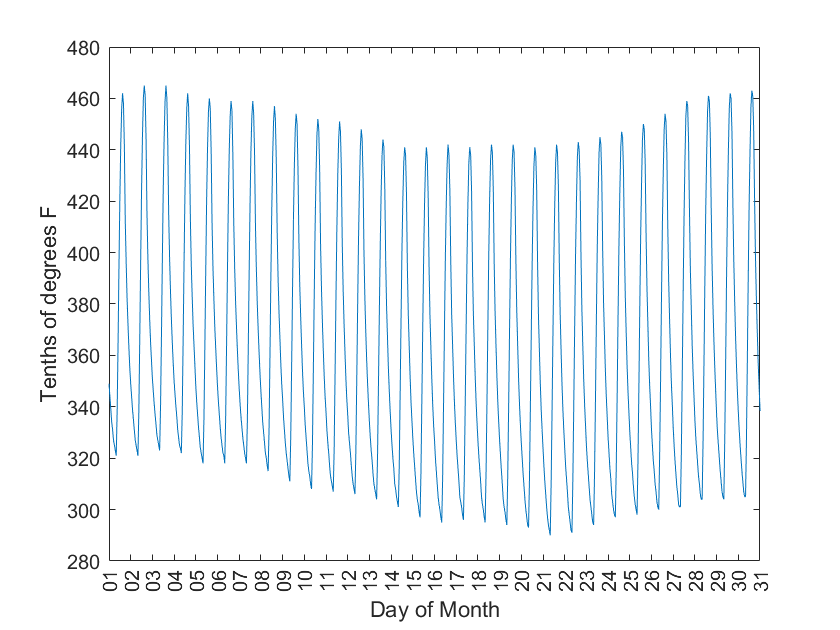

%Now, what is below...you don't need to worry about all of this right now.
%I'm just doing some clever work with the x axis (time) to get it plot up
%really nicely.
datevar=datenum(year,month,day,hour,min,sec);
labeldatevar=unique(datenum(year,month,day));
figure(1)
plot(datevar,data{7})
set(gca,'XTick',labeldatevar)
datetick('x',7,'keepticks');
xlabel('Day of Month');ylabel('Tenths of degrees F')

## BLOCK 9 - READTABLE

Finally. Readtable can be a very powerful function that will read in a file of mixed format. It will place the information into a 'table' which is a different way of storing information (different than matrix, cell array, etc.).

data=readtable('textscaneasy.txt')

You see how it says that data is a 'table'? So, we can't just do math on the columns like we could if it was a matrix:

mean(data(:,2))

So, if you choose to use readtable (which is really cool and flexible) you will have to then convert columns of information into other data types. You can read all about it here: [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html.](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html.) Note that the table is kind of like a structure. If we want to extract the latitude values, we do it like this:

latitude=data.Lat